# Crosswind turbulence length scale

The crosswind turbulence length scales (CTLS) are 2-point integral turbulence characteristics. They requires, therefore, at least 2 sensors monitoring simultaneously the flow. They give an idea of the typical  size of eddies in the crosswind direction [1]. In the present example, only lateral separations are different from zero. Therefore, the CTLSs are are $L^y_u$,$L^y_v$ and $L^y_w$, respectively.  In  [1], the random error was neglected. It is no longer the case hereinafter.

**References**

[1] Cheynet, E. (2016). Wind-induced vibrations of a suspension bridge: A case study in full-scale. PhD thesis. University of Stavanger, Norway

## Load the data

clearvars;close all;clc;
load('data.mat','u','v','w','t','nodes');
[Ny,N]=size(u);
meanU = nanmean(u,2);
dt = median(diff(t));
fs = 1/dt;

## Estimation of the crosswind turbulence length scales

An exponential fit is used here

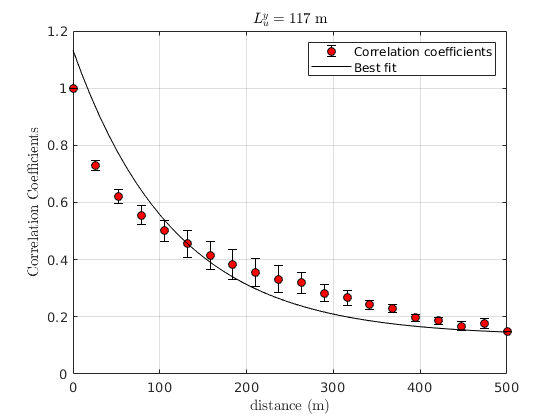

pos = nodes.Y;
[Lu,dataU] = Lyz(u,pos);
[Lv,dataV] = Lyz(v,pos);
[Lw,dataW] = Lyz(w,pos);


d = linspace(0,500,50);
figure
errorbar(dataU.d,dataU.R,dataU.err,'ko','markerfacecolor','r')
hold on
plot(d,dataU.fun(dataU.coeff,d),'k')
set(gcf,'color','w')
xlabel([' distance (m)'],'interpreter','latex')
ylabel(['Correlation Coefficients'],'interpreter','latex')
grid on
legend('Correlation coefficients','Best fit');
title(['$L^y_u = ',num2str(round(Lu)),'$ m'],'interpreter','latex')

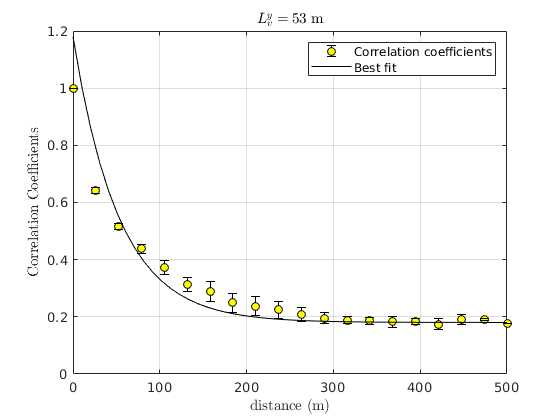



figure
errorbar(dataV.d,dataV.R,dataV.err,'ko','markerfacecolor','y')
hold on
plot(d,dataV.fun(dataV.coeff,d),'k')
set(gcf,'color','w')
xlabel([' distance (m)'],'interpreter','latex')
ylabel(['Correlation Coefficients'],'interpreter','latex')
grid on
legend('Correlation coefficients','Best fit');
title(['$L^y_v = ',num2str(round(Lv)),'$ m'],'interpreter','latex')

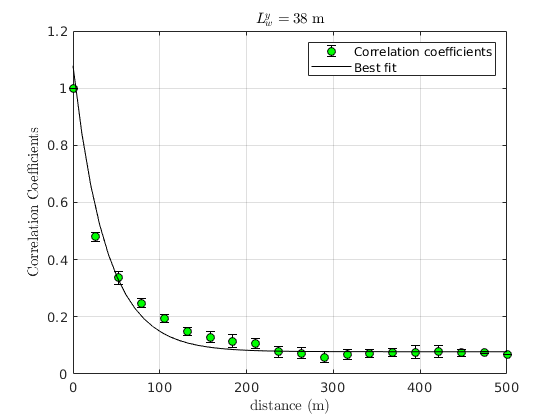


figure
errorbar(dataW.d,dataW.R,dataW.err,'ko','markerfacecolor','g')
hold on
plot(d,dataW.fun(dataW.coeff,d),'k')
set(gcf,'color','w')
xlabel([' distance (m)'],'interpreter','latex')
ylabel(['Correlation Coefficients'],'interpreter','latex')
grid on
legend('Correlation coefficients','Best fit');
title(['$L^y_w = ',num2str(round(Lw)),'$ m'],'interpreter','latex')